clear
c1  = load('Resultados\mediciones 1\control.dat');
t11 = load('Resultados\mediciones 1\tita1.dat');
t21 = load('Resultados\mediciones 1\tita2.dat');
ts1 = load('Resultados\mediciones 1\tiempo.dat');
v11 = load('Resultados\mediciones 1\velocidad1.dat');
v21 = load('Resultados\mediciones 1\velocidad2.dat');
w11 = load('Resultados\mediciones 1\aceleración1.dat');
w21 = load('Resultados\mediciones 1\aceleración2.dat');

c2  = load('Resultados\mediciones 2\control.dat') ;
t12 = load('Resultados\mediciones 2\tita1.dat');
t22 = load('Resultados\mediciones 2\tita2.dat');
ts2 = load('Resultados\mediciones 2\tiempo.dat');
v12 = load('Resultados\mediciones 2\velocidad1.dat');
v22 = load('Resultados\mediciones 2\velocidad2.dat');
w12 = load('Resultados\mediciones 2\aceleración1.dat');
w22 = load('Resultados\mediciones 2\aceleración2.dat');

c3  = load('Resultados\mediciones 3\control.dat') ;
t13 = load('Resultados\mediciones 3\tita1.dat');
t23 = load('Resultados\mediciones 3\tita2.dat');
ts3 = load('Resultados\mediciones 3\tiempo.dat');
v13 = load('Resultados\mediciones 3\velocidad1.dat');
v23 = load('Resultados\mediciones 3\velocidad2.dat');
w13 = load('Resultados\mediciones 3\aceleración1.dat');
w23 = load('Resultados\mediciones 3\aceleración2.dat');

c4  = load('Resultados\mediciones 4\control.dat') ;
t14 = load('Resultados\mediciones 4\tita1.dat');
t24 = load('Resultados\mediciones 4\tita2.dat');
ts4 = load('Resultados\mediciones 4\tiempo.dat');
v14 = load('Resultados\mediciones 4\velocidad1.dat');
v24 = load('Resultados\mediciones 4\velocidad2.dat');
w14 = load('Resultados\mediciones 4\aceleración1.dat');
w24 = load('Resultados\mediciones 4\aceleración2.dat');


# Modelo de estados


$$\left\lbrack \begin{array}{c}
\ddot{\theta_1 } \\
\dot{\theta_1 } \\
\ddot{\theta_2 } \\
\dot{\theta_2 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-q_1 \mathrm{sin}\left(\theta_1 \right)+q_2 \;\dot{\theta_2 } -q_3 \;u\\
\dot{\theta_1 } \\
q_1 \mathrm{sin}\left(\theta_1 \right)-\left(\rho +1\right)q_2 \;\dot{\theta_2 } +\left(\rho +1\right)q_3 \;u\\
\dot{\theta_2 } 
\end{array}\right\rbrack$$


donde definimos


$$\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\theta_1 \\
\dot{\theta_1 } \\
\theta_2 \\
\dot{\theta_2 } 
\end{array}\right\rbrack ,\;\;\;\;\;\mathrm{obteniendo}\;\left\lbrack \begin{array}{c}
\dot{x_2 } \\
\dot{x_4 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-q_1 \mathrm{sin}\left(x_1 \right)+q_2 \;x_4 -q_3 \;u\\
q_1 \mathrm{sin}\left(x_1 \right)-\left(\rho +1\right)q_2 \;x_4 +\left(\rho +1\right)q_3 \;u
\end{array}\right\rbrack$$


luego pasamos al espacio de parametros de la siguiente forma

$\left\lbrack \begin{array}{cccc}
-\mathrm{sin}\left(x_1 \right) & x_4  & -u & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
q_1 \\
q_2 \\
q_3 \\
\rho 
\end{array}\right\rbrack =\dot{x_2 }$`    (ec 1)`

$\dot{x_4 } =-\left(1+\rho \right)\dot{x_2 } -\rho \;q_1 \mathrm{sin}\left(x_1 \right)=-\dot{x_2 } -\rho \left(\dot{x_2 } +q_1 \mathrm{sin}\left(x_1 \right)\right)$`    (ec 2)`

%por tener un producto de parametros en una de las dos ecuaciones
%encontradas necesitamos encontrar los valores que minimizan el error de la
%primera ecuacion y, una vez encontrados, se buscan los parametros
%restantes en la segunda ecuacion

format shortG

[q11 q21 q31 rho1] = paramsSVD(t11,v21,w11,w21,c1);
[q12 q22 q32 rho2] = paramsSVD(t12,v22,w12,w22,c2);
[q13 q23 q33 rho3] = paramsSVD(t13,v23,w13,w23,c3);
[q14 q24 q34 rho4] = paramsSVD(t14,v24,w14,w24,c4);

parametros = table([q11; q12; q13; q14], [q21; q22; q23; q24], [q31; q32; q33; q34], [rho1; rho2; rho3; rho4]);
parametros = renamevars(parametros, ["Var1" "Var2" "Var3" "Var4"],["q_1" "q_2" "q_3" "rho"])

parametros = 4×4 table
     q_1         q_2         q_3         rho   
    ______    _________    ________    ________

    25.508    0.0017842    0.019816      102.82
    24.425    0.0035713    0.013775      268.97
    24.828        25.95         NaN    -0.98386
    26.224    0.0026603    0.010469      225.23


# Simulaciones

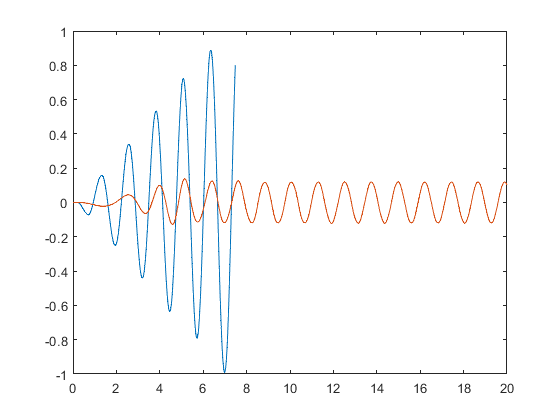

%Condiciones iniciales
x1_0 = t14(1,1);
x2_0 = v14(1,1); %x1p
x2p_0 = w14(1,1);

x3_0 = t24(1,1);
x4_0 = v24(1,1); %x2p
w4p_0 = w24(1,1);

%Control y tiempo
control = c4;
t = ts4;
ts = t(3,1)-t(2,1);

q1  = 26.224;
q2  = 0.0027;
q3  = 0.0105;
rho = 225.2263;
r1 = rho+1;


sim("modelo\modeloDOWNGRADE.mdl")
plot(ts1, t11, t_med, x1)

function [q1, q2, q3, rho] = paramsSVD(x1,x4,x2p,x4p,u)
    %Calculamos SVD de X2P
    if(all(u == 0)) %Si la entrada es cero no la consideramos
        A1 = [-sin(x1) x4];
    else
        A1 = [-sin(x1) x4 -u];
    end
    y = x2p; %velocidad del disco
    
    %%% SVD Solution
    [U,S,V] = svd(A1,'econ');
    
    z = V*S^-1*U'*y;
    q1 = z(1);
    q2 = z(2);
    if(all(u == 0)) %Si la entrada es cero q3 queda indeterminado
        q3 = NaN;
    else
        q3 = z(3);
    end
    
    %Calculamos SVD de X1P utilizando los parametros ya estimados
    A2 = -(x2p + q1*sin(x1));
    y = x4p + x2p;
    
    [U,S,V] = svd(A2,'econ');
    rho = V*S^-1*U'*y;
    
    %Esta forma de estimar los parametros no es de minimo error pero es una
    %buena aproximacion
    
end